clear; clc; close all;

## In the following we sample from Gaussian distribution to generate 3 clusters

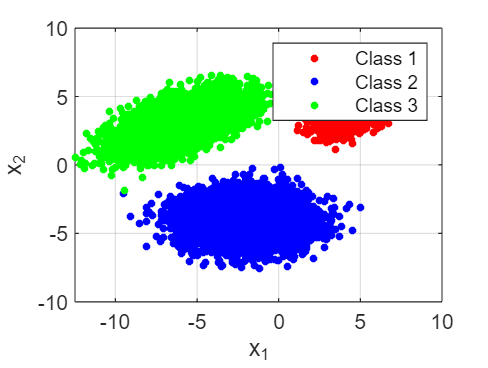

rng(10)
L = 10e3;

mu_1 = [5 5]; % mean
Sigma_1 = [1 0.5; 0.5 1]; % covariance
X_1 = mvnrnd(mu_1,Sigma_1,L); % drawing samples from 2D Gaussian ditribution

mu_2 = [-2 -4];
Sigma_2 = [3 0; 0 1];
X_2 = mvnrnd(mu_2,Sigma_2,L);

mu_3 = [-6 3];
Sigma_3 = [3 1; 1 1];
X_3 = mvnrnd(mu_3,Sigma_3,L);


figure
plot(X_1(:,1),X_1(:,2),'r.','MarkerSize',10), hold on
plot(X_2(:,1),X_2(:,2),'b.','MarkerSize',10),
plot(X_3(:,1),X_3(:,2),'g.','MarkerSize',10), hold off
grid on
xlabel('x_1')
ylabel('x_2')
legend('Class 1','Class 2', 'Class 3')

## Calssification (2 classes)

C_1 = repmat([0,1],[L,1]); % generate labels for Class 1
C_2 = repmat([1,0],[L,1]); % generate labels for Class 2

% data set containing two classes
data_set = [X_1,C_1;X_2,C_2]; % form the data set. Samples X_1 and X_2 belong to Class 1 and 2, respectivelly.

rand_int = randperm(length(data_set)); % random vector generation
%data_set = data_set(rand_int,:); % random shuffling of the data set.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% YOUR CODE BELOW
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%